## **Information:**

**Names : **

Aisha AlKaabi 202001907

Amna Alyafei 201905209

Ayesha Balideh 201803019

**Section: **B54

**Phone Model:** iPhone 13

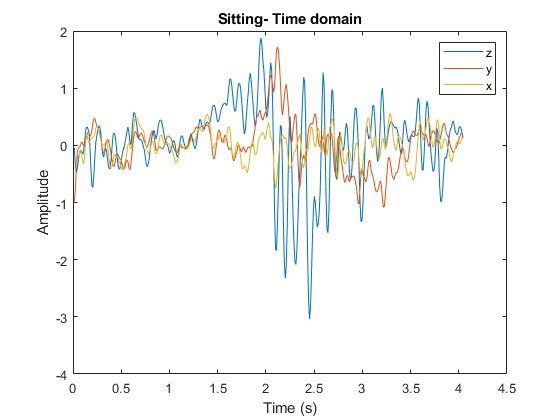

%read data of Sitting
s= csvread('sitting.csv',1,1);
t1 = s(:,1);
z1 = s(:,2);
y1 = s(:,3);
x1 = s(:,4);
Y1 = [z1 y1 x1];
figure, plot(t1, Y1);
title('Sitting- Time domain');
xlabel('Time (s)');
ylabel('Amplitude');
legend('z','y','x');


%fft sitting
N1 = length(Y1);
T1 = max(t1);
SF = fftshift(fft(Y1,N1));
Fs =N1/T1;
%magnitude
S_mag = abs(SF/N1)

S_mag =     0.0006    0.0001    0.0014
    0.0004    0.0002    0.0013
    0.0005    0.0001    0.0015
    0.0007    0.0005    0.0015
    0.0009    0.0000    0.0017
    0.0005    0.0003    0.0014
    0.0013    0.0006    0.0018
    0.0005    0.0003    0.0016
    0.0010    0.0002    0.0017
    0.0007    0.0005    0.0017


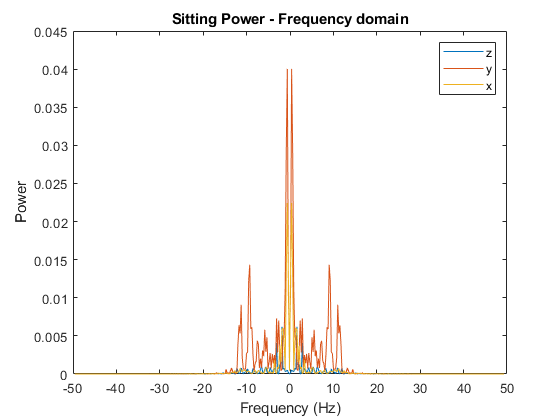

%phase
S_phase = angle(SF);
%power
S_power = S_mag.^2;
%frequency axis
df = Fs/N1;
s1 = -Fs/2 : df : Fs/2-df;
%plot
figure, plot(s1,S_power);
title('Sitting Power - Frequency domain');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('z','y','x');

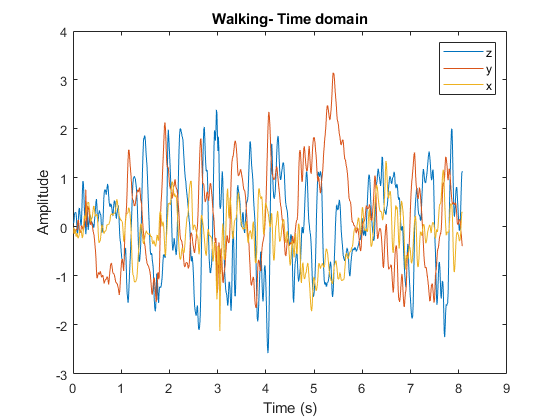




%read data of Walking
w= csvread('walking.csv',1,1);
t2 = w(:,1);
z2 = w(:,2);
y2 = w(:,3);
x2 = w(:,4);
Y2 = [z2 y2 x2];
figure, plot(t2, Y2);
title('Walking- Time domain');
xlabel('Time (s)');
ylabel('Amplitude');
legend('z','y','x');


%fft walking
N2 = length(Y2);
T2 = max(t2);
WF = fftshift(fft(Y2,N2));
Fs2 =N2/T2;
%magnitude
W_mag = abs(WF/N2)

W_mag =     0.0003    0.0005    0.0001
    0.0003    0.0001    0.0000
    0.0001    0.0002    0.0003
    0.0006    0.0010    0.0003
    0.0001    0.0009    0.0005
    0.0003    0.0002    0.0004
    0.0004    0.0008    0.0002
    0.0003    0.0009    0.0007
    0.0009    0.0010    0.0002
    0.0006    0.0005    0.0006


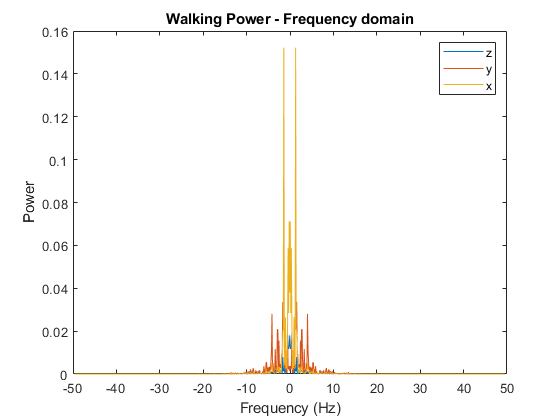

%phase
W_phase = angle(WF);
%power
W_power = W_mag.^2;
%frequency axis
df2 = Fs2/N2;
w = -Fs2/2 : df2 : Fs2/2-df2;
%plot
figure, plot(w,W_power);
title('Walking Power - Frequency domain');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('z','y','x');

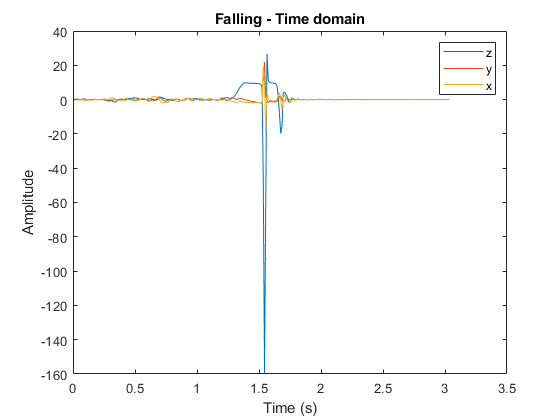




%read data of Falling
f= csvread('falling.csv',1,1);
t3 = f(:,1);
z3 = f(:,2);
y3 = f(:,3);
x3 = f(:,4);
Y3 = [z3 y3 x3];
figure, plot(t3, Y3);
title('Falling - Time domain');
xlabel('Time (s)');
ylabel('Amplitude');
legend('z','y','x');



%fft - falling
N3 = length(Y3);
T3 = max(t3);
FF = fftshift(fft(Y3,N3));
Fs3 =N3/T3;
%magnitude
F_mag = abs(FF/N3)

F_mag =     0.0354    0.1236    0.0266
    0.0360    0.1223    0.0256
    0.0378    0.1199    0.0254
    0.0405    0.1161    0.0268
    0.0427    0.1122    0.0256
    0.0453    0.1093    0.0253
    0.0502    0.1050    0.0264
    0.0532    0.1051    0.0257
    0.0550    0.1055    0.0253
    0.0572    0.1077    0.0286


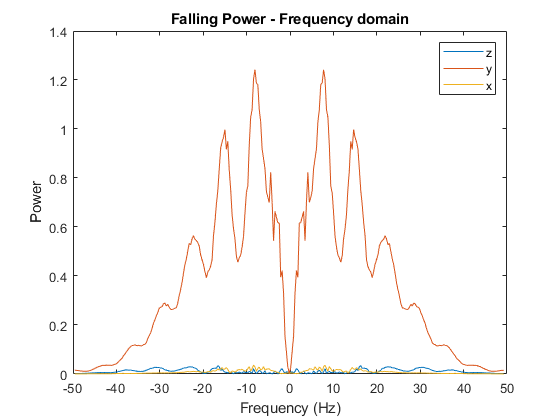

%phase
F_phase = angle(FF);
%power
F_power = F_mag.^2;
%frequency axis
df3 = Fs3/N3;
f = -Fs3/2 : df3 : Fs3/2-df3;
%plot
figure, plot(f,F_power);
title('Falling Power - Frequency domain');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('z','y','x');

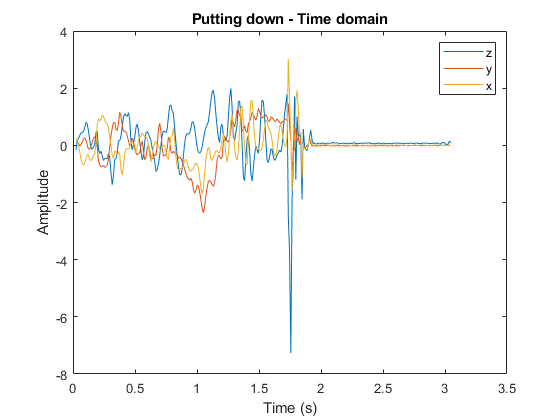




%read data of Putting Down
p= csvread('putting_down.csv',1,1);
t4 = p(:,1);
z4 = p(:,2);
y4 = p(:,3);
x4 = p(:,4);
Y4 = [z4 y4 x4];
figure, plot(t4, Y4);
title('Putting down - Time domain');
xlabel('Time (s)');
ylabel('Amplitude');
legend('z','y','x');



%fft - putting down
N4 = length(Y4);
T4 = max(t4);
PF = fftshift(fft(Y4,N4));
Fs4 =N4/T4;
%magnitude
P_mag = abs(PF/N4)

P_mag =     0.0170    0.0232    0.0082
    0.0165    0.0247    0.0083
    0.0164    0.0249    0.0076
    0.0166    0.0267    0.0078
    0.0141    0.0264    0.0067
    0.0143    0.0270    0.0068
    0.0141    0.0266    0.0074
    0.0128    0.0282    0.0064
    0.0116    0.0304    0.0069
    0.0107    0.0290    0.0058


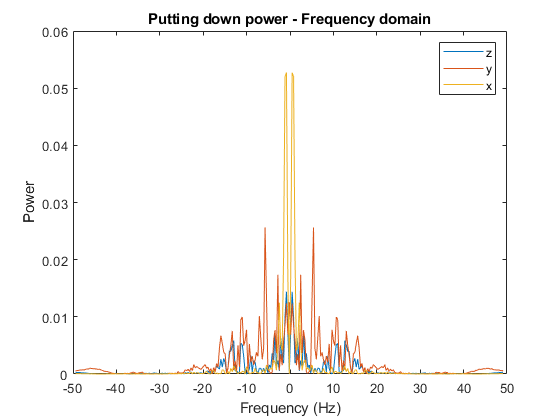

%phase
P_phase = angle(PF);
%power
P_power = P_mag.^2;
%frequency axis
df4 = Fs4/N4;
p = -Fs4/2 : df4 : Fs4/2-df4;
%plot
figure, plot(p,P_power);
title('Putting down power - Frequency domain');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('z','y','x');



%for loop
threshold= 0.2; 
fall = 0;
%sitting  
ymax = max(S_power(:,2)); %extracting the maximum (y-axis Power for Sitting)
for f = 1:N1
    if ymax > threshold
       fall = 1;
    else 
        fall = 0;
    end
end

if fall == 1
    display("Falling");
else
    display("Not falling");
end

    "Not falling"




%for loop 
%walking  
ymax = max(W_power(:,2)); %extracting the maximum (y-axis Power for Walking)
for f = 1:N2
    if ymax > threshold
       fall = 1;
    else 
        fall = 0;
    end
end

if fall == 1
    display("Falling");
else
    display("Not falling");
end

    "Not falling"




%for loop 
%falling 
ymax = max(F_power(:,2)); %extracting the maximum (y-axis Power for Falling)
for f = 1:N3
    if ymax > threshold
       fall = 1;
    else 
        fall = 0;
    end
end

if fall == 1
    display("Falling");
else
    display("Not falling");
end

    "Falling"




%for loop 
%putting down 
ymax = max(P_power(:,2)); %extracting the maximum (y-axis Power for putting down)
for f = 1:N4
    if ymax > threshold
       fall = 1;
    else 
        fall = 0;
    end
end

if fall == 1
    display("Falling");
else
    display("Not falling");
end

    "Not falling"



**Threshold**

We displayed the power spectrum of each position, we noticed that the y values were the variables that changed the most when falling. We extracted the y values for all positions, then taking the maximum to choose a suitable threshold value.  We recognised that the maxium values for positions other than falling, was less than 0.2.

**Power spectrum **

We chose the power spectrum instead of the other spectrums because while having different positions the power which depends on the magnitude was clearly displayed.